# IEEE Signal Processing Cup 2020 - Qualifications

% Team 2 : GMM

## Report

Defining the problem 5 normal and 5 abnormal recordings are given as ROS .bag files.

The task is to implement models which will give a prediction wheter each sample in the recording is normal/abnormal based on measurements from .bag files.

Visualization: Images were extracted from "/pylon_camera_node/image_raw" topic, rotated 180 degrees and saved as video files with 4fps framerate.

From extracted videos we see that the recordings come from some UAV, where the normal recordings were made during stable flight without fast movement while abnormal recordings were made during very unstable flight with sudden movements.

% Preanalysis Every recording has around hundred mesurements but we don't have class labels.

=> We can't use classic classification.

=> Possible solution: Gaussian Mixture Model

% Measurement analysis Based on extracted videos, the following measurements were chosen as relevant for analysis:

"/mavros/global_position/local"

"/mavros/imu/data"

"/mavros/imu/mag"

"/mavros/global_position/compass_hdg"

Time plots and histograms show that the oscillations of some measurements are much larger on abnormal recordings than normal ones.

That means that the derivatives of those signals reach higher absolute values on abnormal recordings, which means that variances of those measurements are larger than on normal recordings so they are deemed as more informative.

Physical quantities that satisfy the above description are orientation, linear velocity, magnetic field and compass heading.

Their derivatives are angular velocity, linear acceleration (already available from IMU), and derivatives of magnetic field and compass heading (which can be calculated from measurements), labeled as:

"IMUAngularVelocity", "IMULinearAcceleration", "MagneticFieldDerivative", "compassHdgDerivative".

First three quantities are 3D, the fourth one is scalar, so the feature vectore is 10D.

% Feature engineering TODO write Gaussian Mixture Model TODO write

% Overview of functions:

%     addDerivative      - calculates derivatives of selected columns of the table and adds the derivative columns.
%     bag2table          - Extracts '/mavros/imu/data', '/mavros/imu/mag', '/mavros/global_position/local'
%                           and '/mavros/global_position/compass_hdg' Topics from ROS .bag file and turns the data into a table.
%     bag2video          - Extracts images from ROS .bag file and saves the stream as video with given parameters.
%     bagCell2table      - Applies bag2table() on bag objects from given cell array and joins the results in one table.
%     bags2video         - Applies bag2video on all bag files from a given directory, returns a cell array of video output objects.
%     compassCell2table  - Converts a cell array of ROS bag 'std_msgs/Float64' type message into a table.
%     files2bag          - Loads all .bag files from given directory into a cell array of bag objects.
%     featureTable       - Data extraction. Applies bag2table() on bag objects from a given cell array,
%                         adds derivatives of magnetic field and compass heading columns, and extracts relevant columns.
%     imu2table          - Converts a ROS bag 'sensor_msgs/Imu' type message into a table.
%     imuCell2table      - Applies imu2table() on elements of a cell array of 'sensor_msgs/Imu' type messages and joins them into a table.
%     mag2table          - Converts ROS bag 'sensor_msgs/MagneticField' type messages into a table.
%     magCell2table      - Applies mag2table() on elements of a cell array of 'sensor_msgs/MagneticField' type messages and joins them into a table.
%     main_GMM_en            - Main program.
%     odom2table         - Converts ROS bag 'nav_msgs/Odometry' type messages into a table.
%     odomCell2table     - Applies odom2table() on elements of a cell array of 'nav_msgs/Odometry' type messages and joins them into a table.
%     plotData           - Plots chosen columns from a pair of tables as signals in time and their histograms.
%                         Used for measurement analysis.

%% Implementation Work directories for normal and abnormal data.

clear;

% change if needed
workDirNormal = '03_normal';
workDirAbnormal = '04_abnormal';

## The structure of data

Loading .bag files, selecting relevant measurements and converting into tables.

bagsNormal = files2bag(workDirNormal);
bagsAbnormal = files2bag(workDirAbnormal);
% Data analysis on joint data from all recordings and choosing predictor features.

jointTableNormal = bagCell2table(bagsNormal);
jointTableAbnormal = bagCell2table(bagsAbnormal);

% close all
Vector3Suffixes = ["X" "Y" "Z"];
QuaternionSuffixes = ["X" "Y" "Z" "W"];

plotData(jointTableNormal, jointTableAbnormal, "odomPosition", Vector3Suffixes, figure(1), figure(2));
% doesn't look useful

plotData(jointTableNormal, jointTableAbnormal, "odomOrientation", QuaternionSuffixes, figure(3), figure(4));
% high frequency oscillations on the abnormal data
% first derivative would be a very useful feature
% angular velocity? 

plotData(jointTableNormal, jointTableAbnormal, "odomTwistLinear", Vector3Suffixes, figure(5), figure(6));
% looks like first derivative would be very useful
% linear acceleration?

plotData(jointTableNormal, jointTableAbnormal, "IMUOrientation", QuaternionSuffixes, figure(7), figure(8));
% this looks identical to odomOrientation

plotData(jointTableNormal, jointTableAbnormal, "IMUAngularVelocity", Vector3Suffixes, figure(9), figure(10));
% just as anticipated, abnormals have much higher variance

plotData(jointTableNormal, jointTableAbnormal, "IMULinearAcceleration", Vector3Suffixes, figure(11), figure(12));
% just as anticipated, abnormals have much higher variance

plotData(jointTableNormal, jointTableAbnormal, "MagneticField", Vector3Suffixes, figure(13), figure(14));
% high frequency oscillations on the abnormal data
% first derivative would be a useful feature

plotData(jointTableNormal, jointTableAbnormal, "compassHdg", "", figure(15), figure(16));
% high frequency oscillations on the abnormal data
% first derivative would be a useful feature

jointTableNormalAddDer = addDerivative(jointTableNormal, "MagneticField", Vector3Suffixes);
jointTableAbnormalAddDer = addDerivative(jointTableAbnormal, "MagneticField", Vector3Suffixes);

jointTableNormalAddDer = addDerivative(jointTableNormalAddDer, "compassHdg");
jointTableAbnormalAddDer = addDerivative(jointTableAbnormalAddDer, "compassHdg");

plotData(jointTableNormalAddDer, jointTableAbnormalAddDer, "MagneticFieldDerivative", Vector3Suffixes, figure(17), figure(18));
% just as anticipated, abnormals have much higher variance

plotData(jointTableNormalAddDer, jointTableAbnormalAddDer, "compassHdgDerivative", "", figure(19), figure(20));
% just as anticipated, abnormals have much higher variance

## Modeling

## Extracting data from bags

% tableNormal = featureTable(bagsNormal);
% tableAbnormal = featureTable(bagsAbnormal);
% save tables.mat tableNormal tableAbnormal -mat

clear; close all; clc;
load('tables.mat')

% tableNormal = [tableNormal, table(zeros(height(tableNormal),1), 'VariableNames', "y")];
% tableAbnormal = [tableAbnormal, table(ones(height(tableAbnormal),1), 'VariableNames', "y")];

## Feature generation

X_normal = tableNormal{:,:};
X_abnormal = tableAbnormal{:,:};

% add lookBack
kLast = 2;
X_normal = lookBack(X_normal, kLast);
X_abnormal = lookBack(X_abnormal, kLast);

% X = [X_normal; X_abnormal];

## Train, CV, Test data split

splitPcg = [50, 25];
[X_normal_train, X_normal_cv, X_normal_test, idx_normal_train, idx_normal_cv, idx_normal_test] = splitData(X_normal, splitPcg);
[X_abnormal_train, X_abnormal_cv, X_abnormal_test, idx_abnormal_train, idx_abnormal_cv, idx_abnormal_test] = splitData(X_abnormal, splitPcg);

X_train = [X_normal_train; X_abnormal_train];
X_cv = [X_normal_cv; X_abnormal_cv];
X_test = [X_normal_test; X_abnormal_test];

M = size(X_train, 1);
M_normal = size(X_normal_train, 1);
M_abnormal = size(X_abnormal_train, 1);

## Feature mapping (scaling and normalization)

mu = 0; %mean(X_train);
% Sigma = cov(X_train);
scalingFactor = 10^(-5);

X_train_mapped = (X_train - mu)* scalingFactor;

## PCA

[coeff,score,latent,tsquared,explained,mu_pca] = pca(X_train_mapped);

varianceRetained = 99;
numComponents = find(cumsum(explained) >= varianceRetained, 1);

disp(['Number of principal components with ' int2str(varianceRetained) '% variance retained: '...
    int2str(numComponents) '/' int2str(size(X_train, 2))]);

Number of principal components with 99% variance retained: 9/30



U = coeff(:,1:numComponents);

Z = (X_train_mapped - mu_pca)* U;

## Training data vizualization

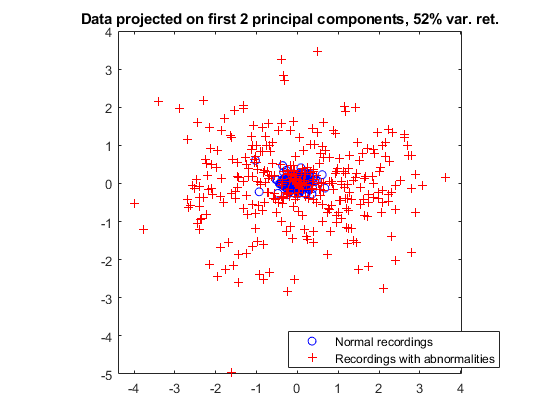

y = [zeros(M_normal,1); ones(M_abnormal,1)];
figure
    gscatter(Z(:,1), Z(:,2), y, 'br', 'o+');
    legend('Normal recordings','Recordings with abnormalities');
    title(['Data projected on first 2 principal components, ' int2str(sum(explained(1:2))) '% var. ret.'])
    axis square

## Gaussian Mixture Model

numClasses = 2;
max_eval = 0;
Iterations = 1000;
for Lambda = [0.0 : 0.005 :0.2]
    disp(['Lambda = ' num2str(Lambda)]);
    [GMM, labelName, normal, abnormal, middle] = gmmFit(Z, numClasses, Lambda, Iterations);
    
    %% Results on CV set
    %% Feature normalization and reduction
    Z_cv = ((X_cv - mu)*scalingFactor - mu_pca) * U;
    
    %% Predict
    P_cv = posterior(GMM, Z_cv);
    [~, y_cv] = max(P_cv, [], 2);
           
    % data for silhouette analysis
    D_cv = silhouetteData(GMM, Z_cv, normal);
    
    %% Silhouette analysis
    s = silhouette(D_cv, y_cv);
    
    % silhouette evaluation
    w_normal = 2.5;
    thresh = 0; %-0.1;
    eval = silhouetteEval(s, y_cv, normal, w_normal, thresh);
    
    disp(['Evaluation (bigger is better): ' num2str(eval)]);
    
    if eval > max_eval
        max_eval = eval;
        GMM_opt = GMM;
%         P_opt = P_cv;
%         D_opt = D_cv;
%         y_opt = y_cv;
        Lambda_opt = Lambda;
        normal_opt = normal;
        abnormal_opt = abnormal;
        labelName_opt = labelName;
    end
    
end

Lambda = 0


Evaluation (bigger is better): 98.3232


Lambda = 0.005


Evaluation (bigger is better): 98.3833


Lambda = 0.01


Evaluation (bigger is better): 98.4286


Lambda = 0.015


Evaluation (bigger is better): 98.4074


Lambda = 0.02


Evaluation (bigger is better): 0


Lambda = 0.025


Evaluation (bigger is better): 98.4073


Lambda = 0.03


Evaluation (bigger is better): 98.4298


Lambda = 0.035


Evaluation (bigger is better): 98.4454


Lambda = 0.04


Evaluation (bigger is better): 0


Lambda = 0.045


Evaluation (bigger is better): 98.4813


Lambda = 0.05


Evaluation (bigger is better): 98.5194


Lambda = 0.055


Evaluation (bigger is better): 98.5677


Lambda = 0.06


Evaluation (bigger is better): 98.5753


Lambda = 0.065


Evaluation (bigger is better): 98.6022


Lambda = 0.07


Evaluation (bigger is better): 98.5989


Lambda = 0.075


Evaluation (bigger is better): 98.5674


Lambda = 0.08


Evaluation (bigger is better): 98.592


Lambda = 0.085


Evaluation (bigger is better): 98.6176


Lambda = 0.09


Evaluation (bigger is better): 98.6585


Lambda = 0.095


Evaluation (bigger is better): 98.6728


Lambda = 0.1


Evaluation (bigger is better): 98.6667


Lambda = 0.105


Evaluation (bigger is better): 98.6301


Lambda = 0.11


Evaluation (bigger is better): 98.6111


Lambda = 0.115


Evaluation (bigger is better): 98.6268


Lambda = 0.12


Evaluation (bigger is better): 98.6071


Lambda = 0.125


Evaluation (bigger is better): 98.6397


Lambda = 0.13


Evaluation (bigger is better): 98.6397


Lambda = 0.135


Evaluation (bigger is better): 98.6719


Lambda = 0.14


Evaluation (bigger is better): 98.6885


Lambda = 0.145


Evaluation (bigger is better): 98.6885


Lambda = 0.15


Evaluation (bigger is better): 98.6607


Lambda = 0.155


Evaluation (bigger is better): 98.75


Lambda = 0.16


Evaluation (bigger is better): 98.8542


Lambda = 0.165


Evaluation (bigger is better): 98.8068


Lambda = 0.17


Evaluation (bigger is better): 98.6585


Lambda = 0.175


Evaluation (bigger is better): 98.5811


Lambda = 0.18


Evaluation (bigger is better): 98.5938


Lambda = 0.185


Evaluation (bigger is better): 98.629


Lambda = 0.19


Evaluation (bigger is better): 98.6607


Lambda = 0.195


Evaluation (bigger is better): 98.75


Lambda = 0.2


Evaluation (bigger is better): 98.75



GMM = GMM_opt;
% P_cv = P_opt;
% D_cv = D_opt;
% y_cv = y_opt;
Lambda = Lambda_opt;
normal = normal_opt;
abnormal = abnormal_opt;
labelName = labelName_opt;

disp(['Optimal Lambda is:' num2str(Lambda_opt)]);

Optimal Lambda is:0.16


## Evaluate on test set

% feature maping and dim. reduction
Z_test = ((X_test - mu)*scalingFactor - mu_pca) * U;

% prediction
P_test = posterior(GMM, Z_test);
[~, y_test] = max(P_test, [], 2);

% data for silhouette analysis
D_test = silhouetteData(GMM, Z_test, normal);

%% Silhouette analysis
s = silhouette(D_test, y_test);

% silhouette evaluation
eval = silhouetteEval(s, y_test, normal, w_normal, thresh);
disp(['Evaluation on test set (bigger is better): ' num2str(eval)])

Evaluation on test set (bigger is better): 99.734


## Visualize predicitons

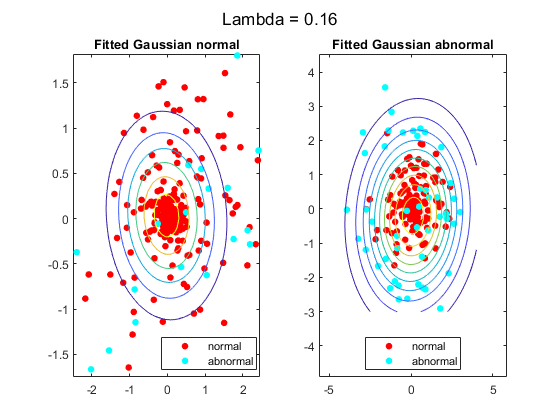

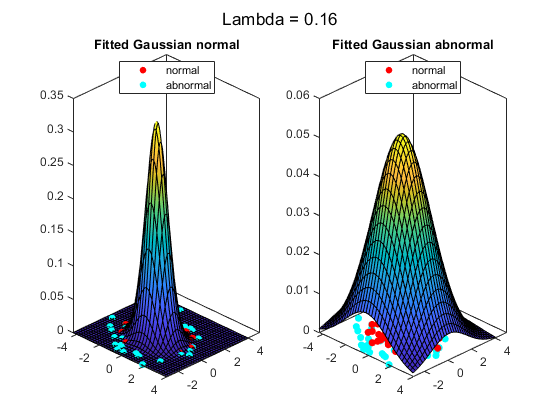

gmm2dVisualization(GMM, Z_test, y_test, labelName, Lambda);

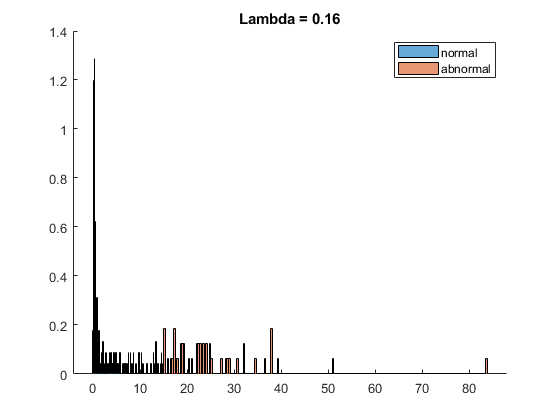

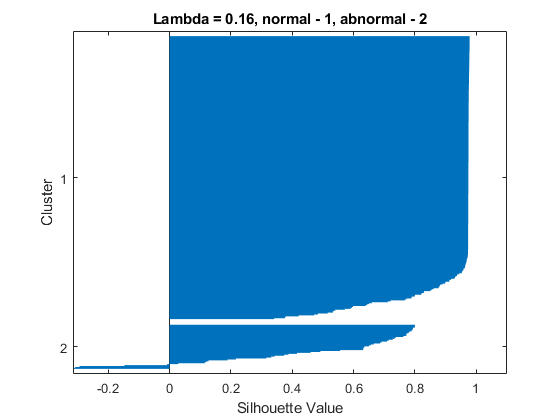

% Silhouettes
[s, h] = silhouetteVisualization(D_test, y_test, numClasses, normal, abnormal, labelName, Lambda);    

## Some statistics

disp(['For Lambda:' num2str(Lambda)]);

For Lambda:0.16



M_pred = [length(find(y_test == normal)), length(find(y_test == abnormal))];
M_test = [length(X_normal_test), length(X_abnormal_test)];

M_pred_conf = [length(find(y_test(1:M_test(1)) == normal)), length(find(y_test(1:M_test(1)) == abnormal));...
               length(find(y_test(M_test(1)+1:end) == normal)), length(find(y_test(M_test(1)+1:end) == abnormal))];

disp(['Num samples normal: ' int2str(M_test(1))])

Num samples normal: 172


disp(['Num samples abnormal: ' int2str(M_test(2))])

Num samples abnormal: 177



disp(['Num predicted normal: ' int2str(M_pred(normal))])

Num predicted normal: 302


disp(['Num predicted abnormal: ' int2str(M_pred(abnormal))])

Num predicted abnormal: 47



disp(['Num predicted normal from normal set: ' int2str(M_pred_conf(1,1))])

Num predicted normal from normal set: 172


disp(['Num predicted abnormal from normal set: ' int2str(M_pred_conf(1,2))])

Num predicted abnormal from normal set: 0


disp(['Num predicted normal from abnormal set: ' int2str(M_pred_conf(2,1))])

Num predicted normal from abnormal set: 130


disp(['Num predicted abnormal from abnormal set: ' int2str(M_pred_conf(2,2))])

Num predicted abnormal from abnormal set: 47


## Time visualization

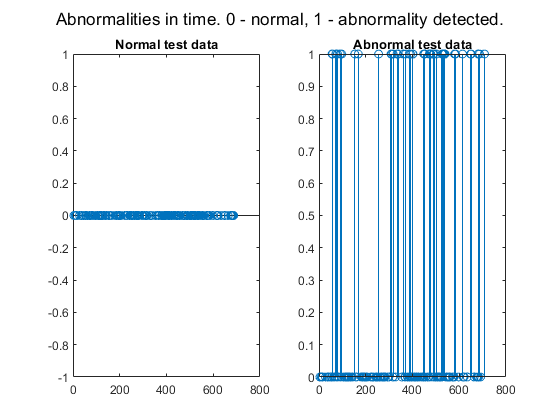

n_normal_normal = idx_normal_test(y_test(1:M_test(1)) == normal);
n_normal_abnormal = idx_normal_test(y_test(1:M_test(1)) == abnormal);
n_abnormal_normal = idx_abnormal_test(y_test(M_test(1)+1:end) == normal);
n_abnormal_abnormal = idx_abnormal_test(y_test(M_test(1)+1:end) == abnormal);

n_normal = kLast + [n_normal_normal n_normal_abnormal];
n_abnormal = kLast + [n_abnormal_normal n_abnormal_abnormal];

y_normal = [zeros(M_pred_conf(1,1), 1); ones(M_pred_conf(1,2), 1)];
y_abnormal = [zeros(M_pred_conf(2,1), 1); ones(M_pred_conf(2,2), 1)];

figure
    subplot(1,2,1)
        stem(n_normal, y_normal);
        title('Normal test data');
    
    subplot(1,2,2)
        stem(n_abnormal, y_abnormal);
        title('Abnormal test data');
    
    sgtitle('Abnormalities in time. 0 - normal, 1 - abnormality detected.');

## Saving the model

save GMM.mat GMM mu scalingFactor mu_pca U -mat
%